# ECE 486 S23 Project Section 4

### @author Laurent Zheng (20818351)

## 1. Analytical IK

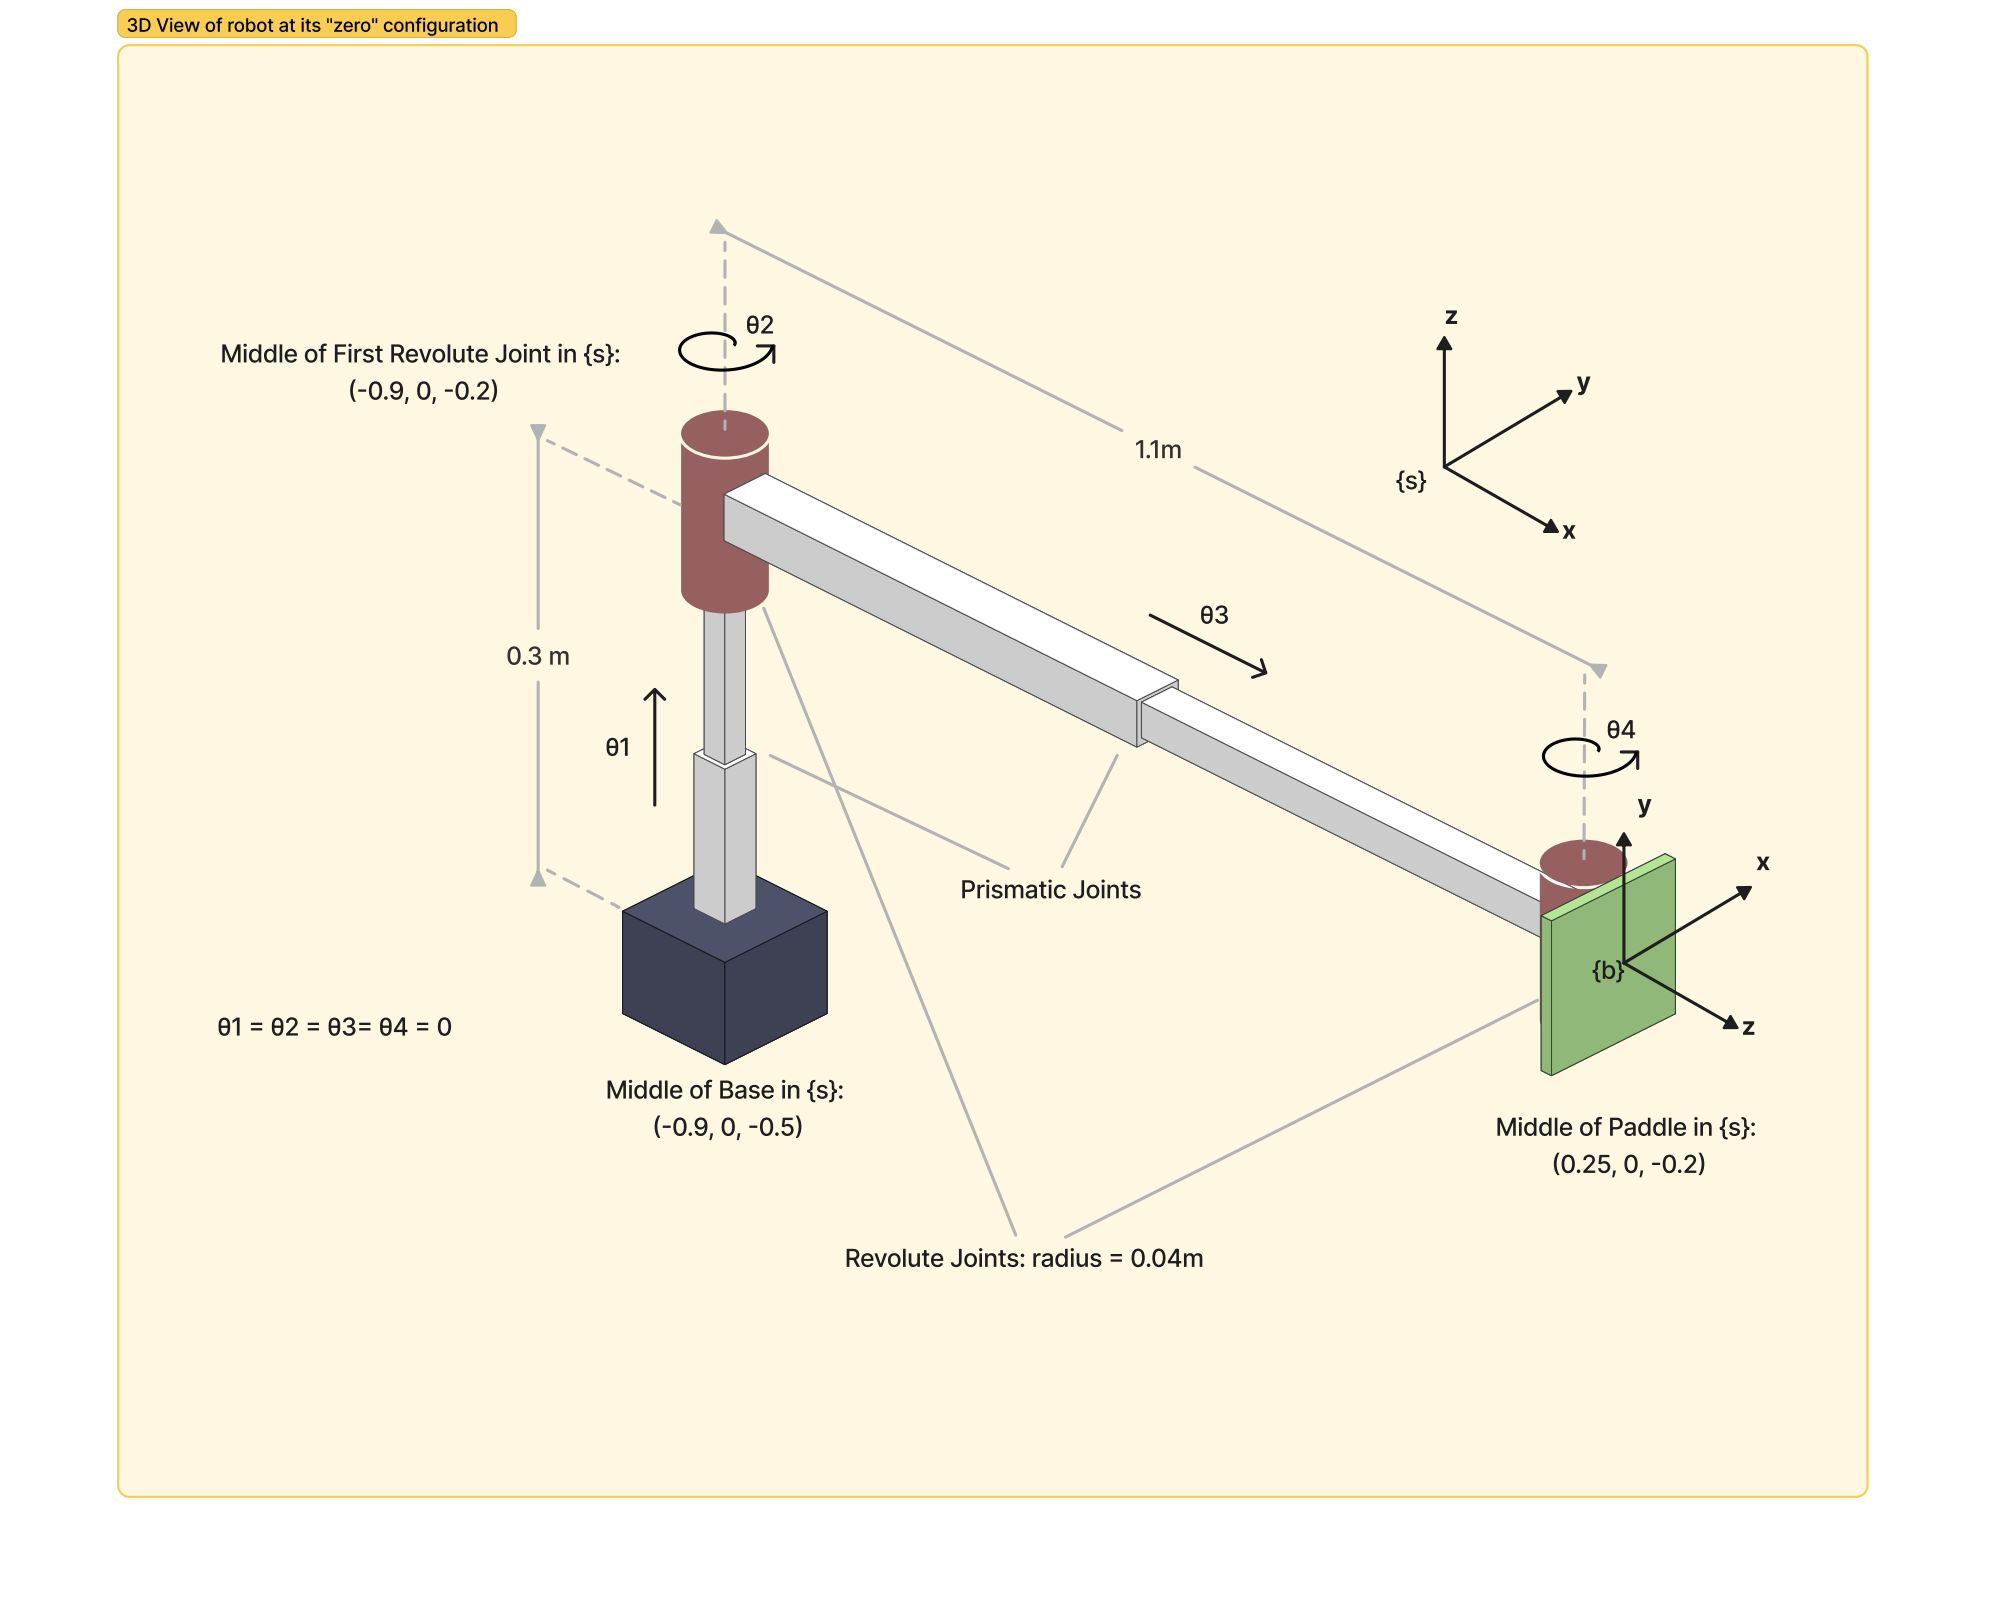

imshow(imread("ECE486 Project Design.png"))

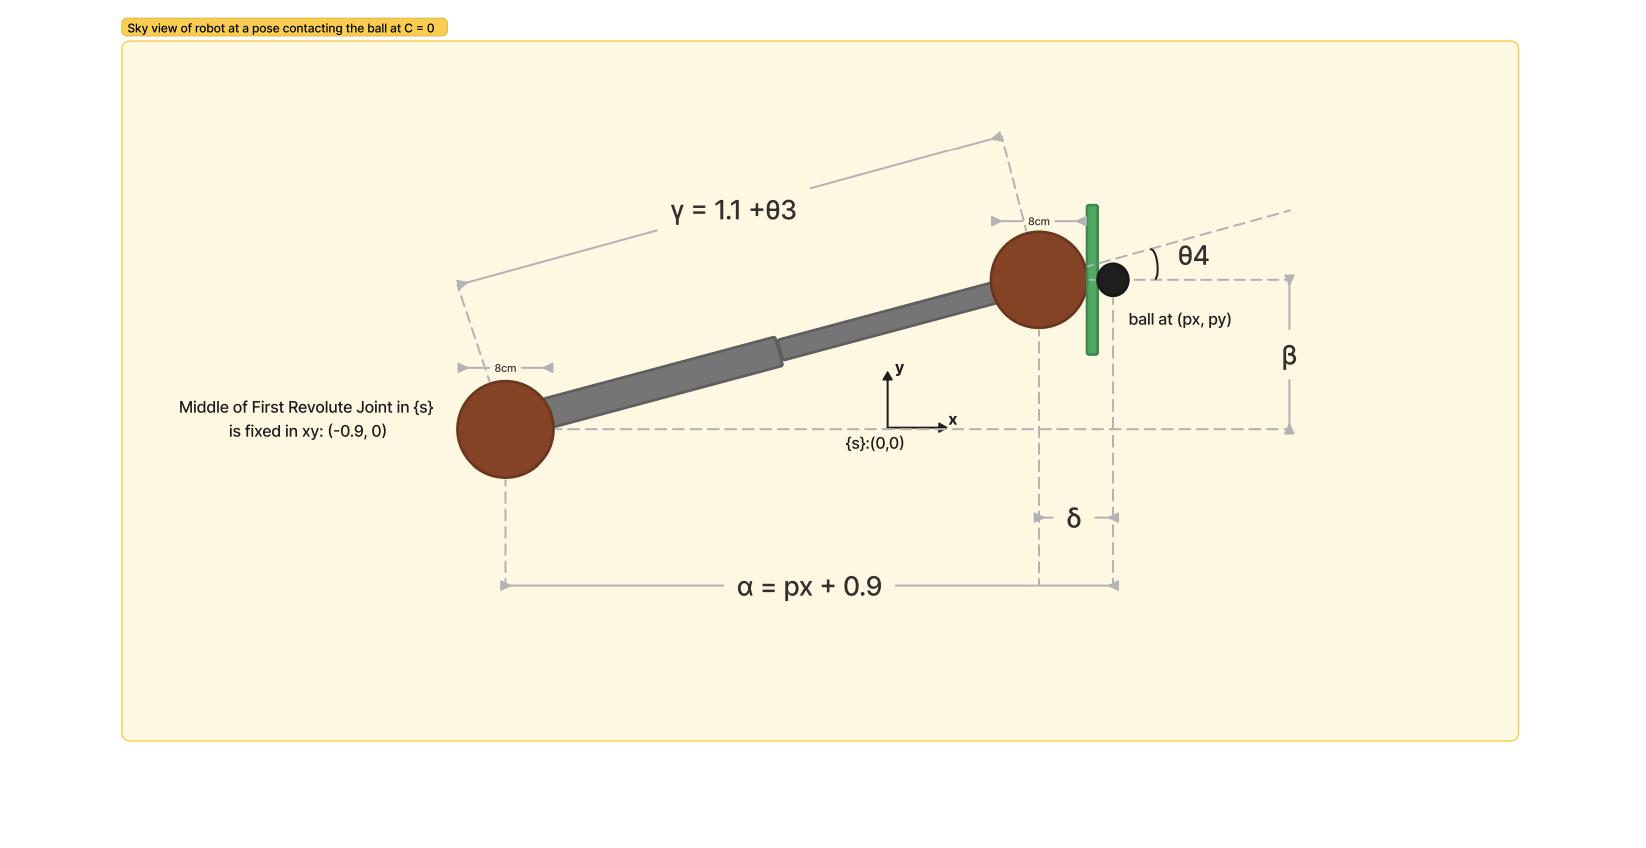

imshow(imread("ECE486 Project IK.png"))

The limits of the joints for $J_1$ to $J_4$ are [0, 1], [0, 1], [$-\pi$, $\pi$], [$-\pi/2$, $\pi/2$] respectively where each joint and links are connected in the first figure shown.

The inverse kinematics maps the position of the ball $^sp_b = [p_x, p_y,p_z]^T$ and a contact angle $C$ to the joint configuration $\Theta  = [\theta_1, \theta_2, \theta_3, \theta_4]^T$ as depicted in the figures above. In our case, we consider intersecting the ball where the centre of the paddle will be in contact. From inspection of the first figure, we can see that $\theta_1$is only a function of $p_z$. Since the middle of the paddle sits at z = -0.2, at the zero configuration, we can write 

$\theta_1  = p_z + 0.2$.

From the sky view depiction(second figure), we can see that the $\theta_2 = atan2(\beta , \alpha - \delta)$, by the relationship of the centre right triangle draw between the two revolute joints(in dotted lines). From inspection, if the first revolute joint is centred at (-0.9, 0) in the x-y plane, then $\alpha = 0.9 + p_x$. On the other hand, $\delta$ depends on the size of the joint, the paddle width, ball size and the angle of contact. This relationship can be written as

$\delta = (r_j + w_p + r_b) cos (C) = (0.04 + 0.01 +0.01)cos(C) = 0.06cos(C)$.

That is the sum of the joint radius, paddle width and ball raidus forms the hypotnuse on $\delta$ and the contact angle $C$.

Using this same relation, we can see Next, when looking at the angle $\beta$ is just $p_y$ with an addtional offset from the oppisite side of the right triangle with respect to $C$. This can be written as

$\beta = p_y + 0.06 sin(C)$.

Finally, putting it all together, we have

$\theta_2 = atan2(p_y+0.06sin(C), 0.9 + p_x - 0.06 cos(C))$.

The prismatic joint offset, $\theta_3$, can then be written as 


$$\theta_3 = \gamma - L_2 = \sqrt{(\alpha - \delta)^2 + \beta^2}-1.1$$



$$= \sqrt{(0.9+px-0.06cos(C))^2+(p_y + 0.06cos(C))^2} - 1.1$$


Lastly, $\theta_4$ is just the contact angle with respect to the link, and can be written as


$$\theta_4 = C - \theta_2$$


We can see that at any unique combinations of $^sp_b$ and $C$, there is only one unique solution to the inverse kinematics. The following shows the robot's configureation at the IK solution to an abitrary input of position and contact angle of the ball. (Note, we only consider contacting the ball at the centre of the paddle).

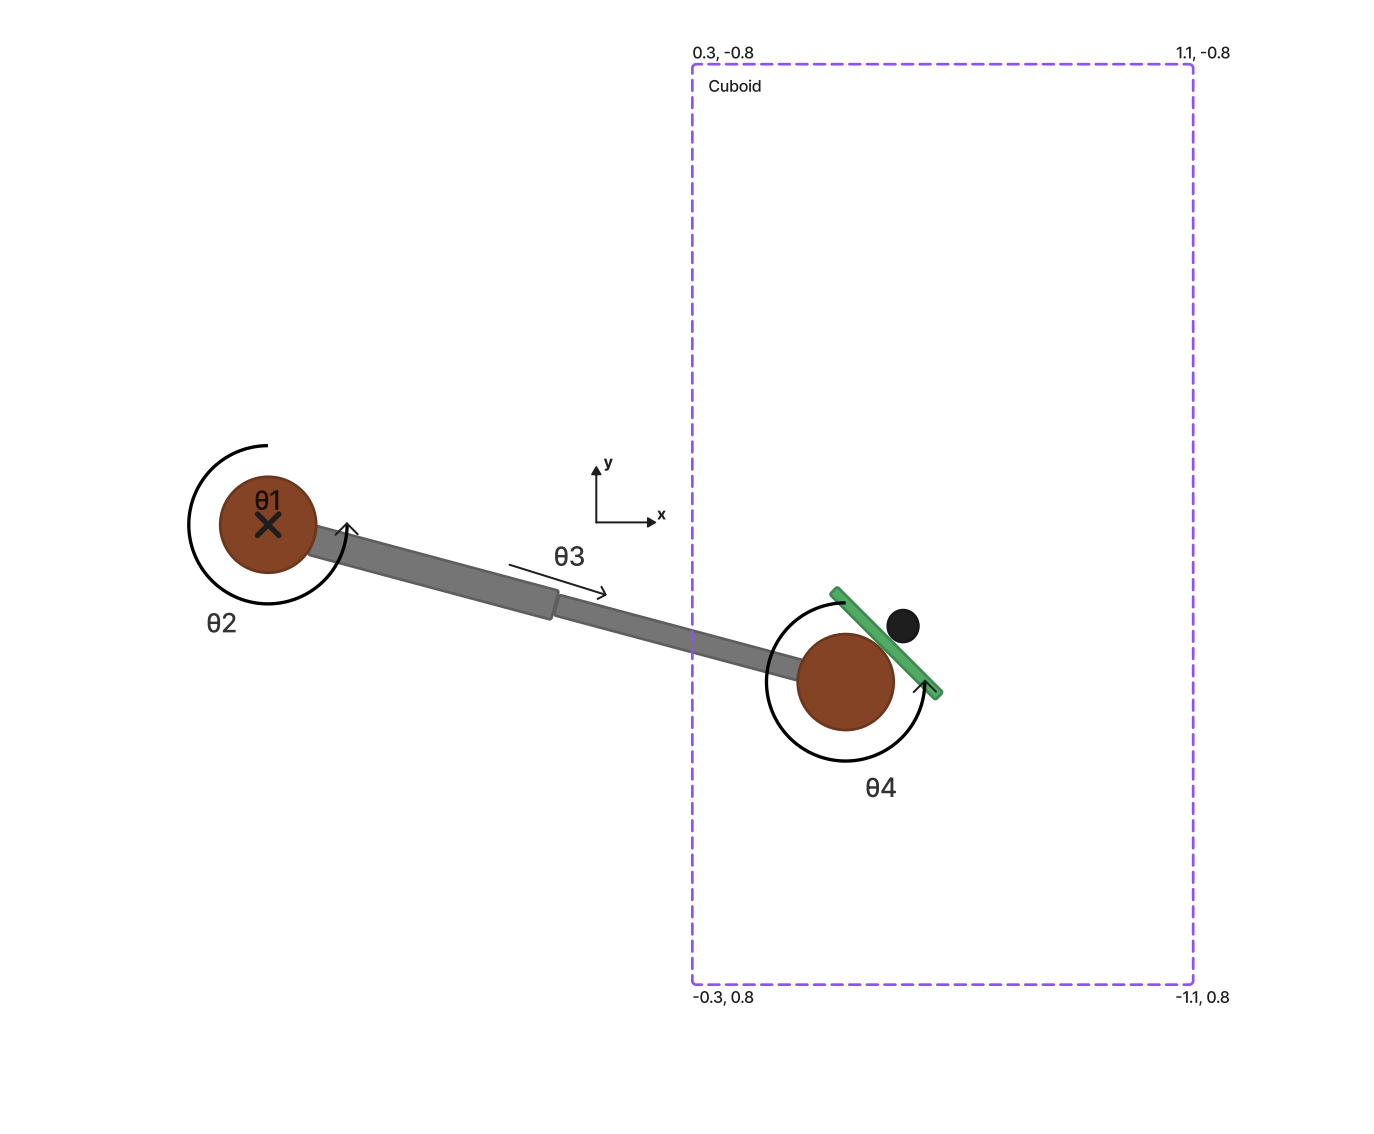

imshow(imread("ECE486 Project Pose.png"))

## 2. Function Definitions for IK and Trajectory Generation.

The inverse kinematics function is neccesary for the trajectory generation. Furthermore, it is also useful for the dynamics section of the project as we need to satisfy the limits on joint torques by analyzing the difference between initial and final theta values of each joint. The trajectory generations function is useful in the control section of the project. We can take advantage of knowing the desire trajectory to see how close we are at each point of the actual trajectory when controlling the joints in a feedback loop.

% Constants:
% T_sh - home pose of the paddle (relative to the fixed frame)
R_sh = [0 0 1; 1 0 0; 0 1 0];
p_sh = [0.25; 0; 0.25];
T_sh = RpToTrans(R_sh, p_sh);

% Define joint_types, joint_limits, B_list, S_list, and M
joint_types = ['P','R','P','R'];
joint_limits = [[0;1],[-pi;pi],[0;1],[-pi/2;pi/2]];
S_list = [[0;0;0;0;0;1],[0;0;1;0;0.9;0]  ,[0;0;0;1;0;0],[0;0;1;0;-0.2;0]];
B_list = [[0;0;0;0;1;0],[0;1;0;1.2;0;0],[0;0;0;0;0;1],[0;1;0;0.5;0;0]]; 
M = [0 0 1 0.25; 1 0 0 0; 0 1 0 -0.2; 0 0 0 1];
n_joints = length(joint_types);

We can test the functions at the corners of the cuboid to make sure that we are within our limits:

[~, ik1] = inverse_kinematics([1.1, 0.8, 0.7])

ik1 =     0.9000    0.3911    0.9985   -0.3911


temp = ik1(1,:)'

temp =     0.9000
    0.3911
    0.9985
   -0.3911


traj1 = generate_trajectory([1.1, 0.8, 0.7], 2, 5)

traj1 =     0.4500         0         0         0
    0.4626    0.0110    0.0280   -0.0110
    0.4968    0.0407    0.1038   -0.0407
    0.5472    0.0845    0.2157   -0.0845
    0.6084    0.1377    0.3515   -0.1377
    0.6750    0.1956    0.4992   -0.1956
    0.7416    0.2534    0.6470   -0.2534
    0.8028    0.3066    0.7828   -0.3066
    0.8532    0.3504    0.8946   -0.3504
    0.8874    0.3802    0.9705   -0.3802


[~, ik2] = inverse_kinematics([1.1, -0.8, 0.7])

ik2 =     0.9000   -0.3911    0.9985    0.3911


traj2 = generate_trajectory([1.1, -0.8, 0.7], 2, 5)

traj2 =     0.4500         0         0         0
    0.4626   -0.0110    0.0280    0.0110
    0.4968   -0.0407    0.1038    0.0407
    0.5472   -0.0845    0.2157    0.0845
    0.6084   -0.1377    0.3515    0.1377
    0.6750   -0.1956    0.4992    0.1956
    0.7416   -0.2534    0.6470    0.2534
    0.8028   -0.3066    0.7828    0.3066
    0.8532   -0.3504    0.8946    0.3504
    0.8874   -0.3802    0.9705    0.3802


[~, ik3] = inverse_kinematics([1.1, -0.8, -0.1])

ik3 =     0.1000   -0.3911    0.9985    0.3911


traj3 = generate_trajectory([1.1, -0.8, -0.1], 2, 5)

traj3 =     0.4500         0         0         0
    0.4402   -0.0110    0.0280    0.0110
    0.4136   -0.0407    0.1038    0.0407
    0.3744   -0.0845    0.2157    0.0845
    0.3268   -0.1377    0.3515    0.1377
    0.2750   -0.1956    0.4992    0.1956
    0.2232   -0.2534    0.6470    0.2534
    0.1756   -0.3066    0.7828    0.3066
    0.1364   -0.3504    0.8946    0.3504
    0.1098   -0.3802    0.9705    0.3802


[~, ik4] = inverse_kinematics([1.1, 0.8, -0.1])

ik4 =     0.1000    0.3911    0.9985   -0.3911


traj4 = generate_trajectory([1.1, 0.8, -0.1], 2, 5)

traj4 =     0.4500         0         0         0
    0.4402    0.0110    0.0280   -0.0110
    0.4136    0.0407    0.1038   -0.0407
    0.3744    0.0845    0.2157   -0.0845
    0.3268    0.1377    0.3515   -0.1377
    0.2750    0.1956    0.4992   -0.1956
    0.2232    0.2534    0.6470   -0.2534
    0.1756    0.3066    0.7828   -0.3066
    0.1364    0.3504    0.8946   -0.3504
    0.1098    0.3802    0.9705   -0.3802


function [T_sc, solution_list] = inverse_kinematics(var)
if size(var)==[4 4] & TestIfSE3(var)
    % The input variable is in SE(3), so set T_sc to the input
    T_sc = var;
    [~,p_sb] = TransToRp(var);
else
    % The input variable is not in SE(3), so set p_sb to the input
    p_sb = reshape(var,[3,1]);

    % Generate a desired contact pose T_sc given the ball position p_sb
    % Note: Copy this section from the IK problem in Section 4: Validation
    R_sh = [0 0 1; 1 0 0; 0 1 0];
    p_sh = [0.25; 0; 0.25];
    T_sh = RpToTrans(R_sh, p_sh);
    
    contact_angle = 0;
    p_hb = T_sh \ [p_sb; 1];
    p_hb = p_hb(1:end-1);
    
    R_hc = [cos(contact_angle) 0 sin(contact_angle); 0 1 0; -sin(contact_angle) 0 cos(contact_angle)];
    p_hc = p_hb - (R_hc * [0; 0; 0.01]);
    T_hc = RpToTrans(R_hc, p_hc);
    
    T_sc = T_sh * T_hc;
end

% For simplicity, we can just always use a contact angle of 0 -> hit the
% ball straight.
contact_angle = 0;
    
% calculation follows derivation above (Here we just merged delta into alpha)
alpha = p_sb(1) + 0.9 - cos(contact_angle)*0.06;
beta = p_sb(2) + sin(contact_angle)*0.06;
theta1 = 0.2 + p_sb(3);
theta2 = atan2(beta, alpha);
theta3 = sqrt(beta.^2 + alpha.^2) - 1.1;
theta4 = contact_angle - theta2;
sol = [theta1, theta2, theta3, theta4];
solution_list = [];

% check if ball is in cuboid before assigning solution: NOTE only one
% unique solution in our case.
if p_sb(1) >= 0.3 && p_sb(1) <= 1.1 && ...
   p_sb(2) >= -0.8 && p_sb(2) <= 0.8 && ...
   p_sb(3) >= -0.1 && p_sb(3) <= 0.7
    solution_list = sol;
end

end

function joint_traj = generate_trajectory(p_sb, t_c, freq)
% Find all valid configurations which contact the ball at p_sb
[~, goal_configs] = inverse_kinematics(p_sb);
if isempty(goal_configs)
    joint_traj = [];
    return;
end

% Find a valid trajectory for your robot to follow to end up with the paddle at rest in pose T_sc at or before t_c

home_configs = [0.45,0,0,0];

ts = 1/freq;
T = t_c;
t = 0:ts:T;
% 3rd order time saling trajectory
time_f = (3.*t.^2/T.^2 - 2.*t.^3/T.^3).';

joint_traj = home_configs + time_f*(goal_configs - home_configs);

end